%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Demo for Modulated Wideband Converter %
%             Version 1.0               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear,close all

## Signal model

SNR = 10;                                   % Input SNR
N = 6;                                      % Number of bands (when counting  a band and its conjugate version separately)
B = 50e6;                                   % Maximal width of each band
Bi = ones(1,N/2)*B;
fnyq = 10e9;                                % Nyquist rate
Ei = rand(1,N/2)*10;                        % Energy of the i'th band
Tnyq = 1/fnyq;
R = 1;                                      % The length of the signal is R*(K+K0)*L
K = 91;
K0 = 10;                                    % R*K0*L is reserved for padding zeros
L = 195;
TimeResolution = Tnyq/R;
TimeWin = [0  L*R*K-1 L*R*(K+K0)-1]*TimeResolution; % Time interval in which signal is observed
Taui = [0.7 0.4 0.3]*max(TimeWin);          % Time offest of the i'th band

fprintf(1,'---------------------------------------------------------------------------------------------\n');

---------------------------------------------------------------------------------------------


fprintf(1,'Signal model\n');

Signal model


fprintf(1,'   N= %d, B=%3.2f MHz, fnyq = %3.2f GHz\n', N, B/1e6, fnyq/1e9);

   N= 6, B=50.00 MHz, fnyq = 10.00 GHz


## Sampling parameters 信号参数

ChannelNum = 50;                            % Number of channels
L = 195;                                    % Aliasing rate
M = 195;
fp = fnyq/L;
fs = fp;                                    % Sampling rate at each channel, use fs=qfp, with odd q
m = ChannelNum;                             % Number of channels

% sign alternating  mixing
SignPatterns = randsrc(m,M);                % Draw a random +-1 for mixing sequences

% calucations
Tp = 1/fp;
Ts = 1/fs;
L0 = floor(M/2);                            
L = 2*L0+1;

fprintf(1,'---------------------------------------------------------------------------------------------\n');

---------------------------------------------------------------------------------------------


fprintf(1,'Sampling parameters\n');

Sampling parameters


fprintf(1,'   fp = %3.2f MHz, m=%d, M=%d\n',fp/1e6,m,M);

   fp = 51.28 MHz, m=50, M=195


fprintf(1,'   L0 = %d, L=%d, Tp=%3.2f uSec, Ts=%3.2f uSec\n', L0, L, Tp/1e-6, Ts/1e-6);

   L0 = 97, L=195, Tp=0.02 uSec, Ts=0.02 uSec


## Signal Representation  信号表示

t_axis = TimeWin(1)  : TimeResolution : TimeWin(end);     % Time axis
t_axis_sig  = TimeWin(1)  : TimeResolution : TimeWin(2);

fprintf(1,'---------------------------------------------------------------------------------------------\n');

---------------------------------------------------------------------------------------------


fprintf(1,'Continuous representation\n');

Continuous representation


fprintf(1,'   Time  window = [%3.2f , %3.2f) uSec\n',TimeWin(1)/1e-6, TimeWin(2)/1e-6 );

   Time  window = [0.00 , 1.77) uSec


fprintf(1,'   Time resolution = %3.2f nSec, grid length = %d\n', TimeResolution/1e-9, length(t_axis));

   Time resolution = 0.10 nSec, grid length = 19695


fprintf(1,'---------------------------------------------------------------------------------------------\n');

---------------------------------------------------------------------------------------------


fprintf(1,'Generating signal\n');

Generating signal


% Signal Generation
x = zeros(size(t_axis_sig));
fi = rand(1,N/2)*(fnyq/2-2*B) + B;      % Draw random carrier within [0, fnyq/2]
for n=1:(N/2)
    x = x+sqrt(Ei(n)) * sqrt(Bi(n))*sinc(Bi(n)*(t_axis_sig-Taui(n))) .* cos(2*pi*fi(n)*(t_axis_sig-Taui(n)));
end
han_win = hann(length(x))';             % Add window  汉明窗
x = x.*han_win;
x = [x, zeros(1,R*K0*L)];               % Zero padding

% Calculate original support set
Sorig = [];
% explain:  we take the starting edges: fi-B/2  and divide by fp. minus
% 0.5 to shift half fp towards zero. then M0+1 is to move 0 = M0+1.
Starts = ceil((fi-B/2)/fp-0.5+L0+1);
Ends = ceil((fi+B/2)/fp-0.5+L0+1);
for i=1:(N/2)
    Sorig = union (Sorig,  Starts(i):Ends(i));
end
% Now add the negative frequencies
Sorig = union(Sorig, L+1-Sorig);
Sorig = sort(Sorig);

## Noise Generation

noise_nyq = randn(1,(K+K0)*L);              % Generate white Gaussian nosie within [-fnyq,fnyq]
noise = interpft(noise_nyq, R*(K+K0)*L);    % Interpolate into a finer grid (the same length as the signal)

% Calculate energies
NoiseEnergy = norm(noise)^2;
SignalEnergy = norm(x)^2;
CurrentSNR = SignalEnergy/NoiseEnergy;

## Mixing

fprintf(1,'Mixing\n');

Mixing



MixedSigSequences = zeros(m,length(t_axis));
for channel=1:m
    MixedSigSequences(channel,:) = MixSignal(x,t_axis,SignPatterns(channel,:),Tp);
end

MixedNoiseSequences = zeros(m,length(t_axis));
for channel=1:m
    MixedNoiseSequences(channel,:) = MixSignal(noise,t_axis,SignPatterns(channel,:),Tp);
end

## Analog low-pass filtering and actual sampling

fprintf(1,'Filtering and decimation (=sampling)\n');

Filtering and decimation (=sampling)


% ideal pass filter
temp = zeros(1,K+K0);
temp(1) = 1;
lpf_z = interpft(temp,length(t_axis))/R/L; % impulse response

SignalSampleSequences = zeros(m,K+K0);
NoiseSampleSequences = zeros(m,K+K0);
fprintf(1,'    Channel ');

    Channel 

decfactor = L*R;
for channel = 1:m
    fprintf(1,'.');  if ( (mod(channel,5)==0) || (channel==m)) fprintf(1,'%d',channel); end
    SignalSequence =  MixedSigSequences(channel,:);
    NoiseSequence   =  MixedNoiseSequences(channel,:);
    DigitalSignalSamples(channel, :) = FilterDecimate(SignalSequence,decfactor,lpf_z);
    DigitalNoiseSamples(channel, :) = FilterDecimate(NoiseSequence,decfactor,lpf_z);
end

.....5.....10.....15.....20.....25.....30.....35.....40.....45.....50

Digital_time_axis = downsample(t_axis,decfactor);
DigitalLength = length(Digital_time_axis);

fprintf(1,'\n---------------------------------------------------------------------------------------------\n');


---------------------------------------------------------------------------------------------


fprintf(1,'Sampling summary\n');

Sampling summary


fprintf(1,'   %d channels, each gives %d samples\n',m,DigitalLength);

   50 channels, each gives 101 samples


## CTF block

fprintf(1,'---------------------------------------------------------------------------------------------\n');

---------------------------------------------------------------------------------------------


fprintf(1,'Entering CTF block\n');

Entering CTF block



% define matrices for fs=fp
S = SignPatterns;
theta = exp(-j*2*pi/L);
F = theta.^([0:L-1]'*[-L0:L0]);
np = 1:L0;
nn = (-L0):1:-1;
% This is for digital input only. Note that when R -> infinity,
% D then coincides with that of the paper
dn = [   (1-theta.^nn)./(1-theta.^(nn/R))/(L*R)      1/L    (1-theta.^np)./(1-theta.^(np/R))/(L*R)];
D = diag(dn);
A = S*F*D;
A = conj(A);

SNR_val = 10^(SNR/10);          % not dB
% combine signal and noise
DigitalSamples = DigitalSignalSamples + DigitalNoiseSamples*sqrt(CurrentSNR/SNR_val);

% Frame construction
Q = DigitalSamples* DigitalSamples';
% decompose Q to find frame V
NumDomEigVals= FindNonZeroValues(eig(Q),5e-8);
[V,d] = eig_r(Q,min(NumDomEigVals,2*N));
v = V*diag(sqrt(d));
% N iterations at most, since we force symmetry in the support...
[u, RecSupp] = RunOMP_Unnormalized(v, A, N, 0, 0.01, true);
RecSuppSorted = sort(unique(RecSupp));
% Decide on success
if (is_contained(Sorig,RecSuppSorted)  && (rank(A(:,RecSuppSorted)) == length(RecSuppSorted)))
    Success= 1;
    fprintf('Successful support recovery\n');
else
    Success = 0;
    fprintf('Failed support recovery\n');
end

Successful support recovery


## Recover the singal

A_S = A(:,RecSuppSorted);
hat_zn = pinv(A_S)*DigitalSamples;  % inverting A_S
hat_zt = zeros(size(hat_zn,1),length(x));
for ii = 1:size(hat_zt,1)                     % interpolate (by sinc)
    hat_zt(ii,:) = interpft(hat_zn(ii,:),L*R*length(hat_zn(ii,:)));
end

x_rec = zeros(1,length(x));
for ii = 1:size(hat_zt,1)                      % modulate each band to their corresponding carriers
    x_rec = x_rec+hat_zt(ii,:).*exp(j*2*pi*(RecSuppSorted(ii)-L0-1)*fp.*t_axis);
end
x_rec = real(x_rec);

sig = x + noise*sqrt(CurrentSNR/SNR_val);

## Analysis & Plots

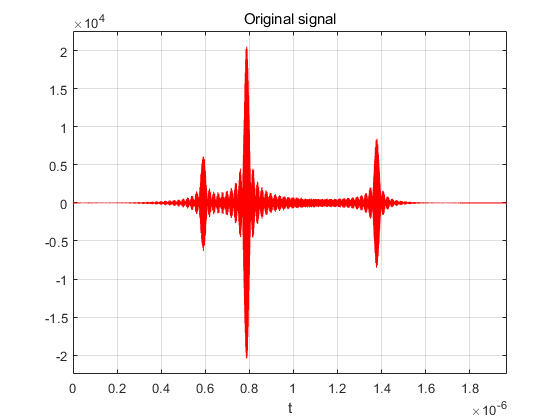

figure,
plot(t_axis,x,'r'), axis([t_axis(1) t_axis(end) 1.1*min(x) 1.1*max(x) ])
title('Original signal'), xlabel('t')
grid on

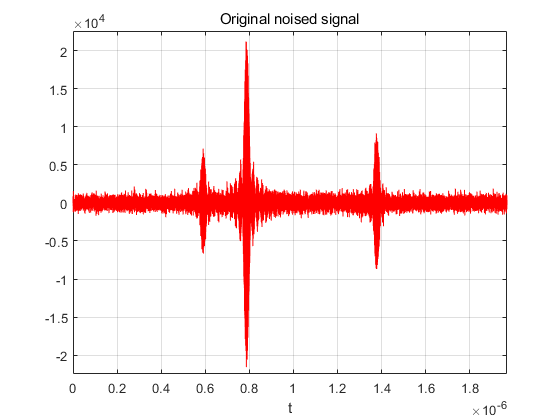

figure,plot(t_axis,sig,'r'), axis([t_axis(1) t_axis(end) 1.1*min(x) 1.1*max(x) ])
title('Original noised signal'), xlabel('t')
grid on

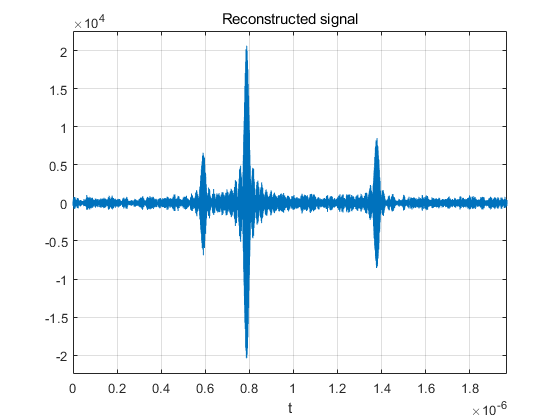

figure, plot(t_axis,x_rec), axis([t_axis(1) t_axis(end) 1.1*min(x) 1.1*max(x) ]),
grid on,
title('Reconstructed signal'), xlabel('t')

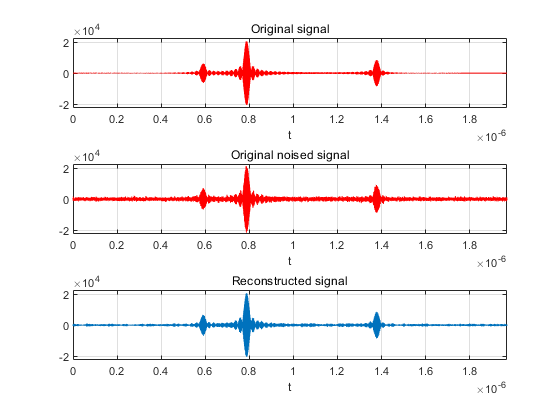


figure,
subplot(3,1,1);
plot(t_axis,x,'r'), axis([t_axis(1) t_axis(end) 1.1*min(x) 1.1*max(x) ])
title('Original signal'), xlabel('t')
grid on
subplot(3,1,2);
plot(t_axis,sig,'r'), axis([t_axis(1) t_axis(end) 1.1*min(x) 1.1*max(x) ])
title('Original noised signal'), xlabel('t')
grid on
subplot(3,1,3);
plot(t_axis,x_rec), axis([t_axis(1) t_axis(end) 1.1*min(x) 1.1*max(x) ]),
grid on,
title('Reconstructed signal'), xlabel('t')